# HTE System Identification

# Manuel Osses

This Matlab Live Scrip was written for the System identification Home taken exam. The script follows the system identification workflow learned in theory. The following steps are followed: 

- Experiment design

- Selectin model structure 

- Apply estimation routine 

- Validation of the models

The script also tries to follow the structure of the Home Taken Assignment of December 19th, 2022

clc,clear, close all;

**Load variables for Simulink simulation **

load('ts_force.mat');
load('time_force.mat');
load("t.mat");
load('data_force.mat');
load_system("ssc_simple_mechanical_system_Manuel.slx");
% load_system("ssc_simple_mechanical_system.slx");
SimTime=10;
Switch=0;

Ts=0.01;    %Calculated from section 1 Defining the sample time.
set_param('ssc_simple_mechanical_system_Manuel/From Workspace','commented','on'); %Comment out the imput U created at section 2
sim("ssc_simple_mechanical_system_Manuel.slx");

**1- Defining the sampling time**

Calculate the risetime to get an indication for the sampling time:

The rise time was defined as the time required for the waveform to go from 0.1 of the final value to 0.9 of the final value (Norman S. Nise).

Steday state value=0.24

0.9*0.24= 0.2160

0.10.24=0.024

Looking to the scope Lever C position it gives a time of:

time diference=0.077

Risetime/10=0.0077

The value of 0.0077 was rounded to 0.010.This makes the calculations easier and the diference is not significant. Ploting the response with a sampletime 0f 0.010 gives figure 1 wich looks  the same as the figure showed in scope Lever C position.

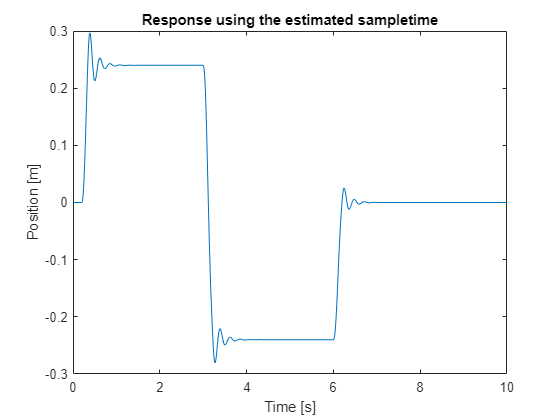

%Make plot of the obtained data with the selected sampletime
t=0:Ts:SimTime;
figure(1)
plot(t,Position)
title('Response using the estimated sampletime')
ylabel('Position [m]')
xlabel('Time [s]')

### **Part 2 Design an input signal and part 5  create iddentification objects**

An experiment was created to generate input/output data for the system identification. A simulation time of 90 seconds was used. PRBS was created using the command idinput. There was special attention on choosing the band for the input signal since it has to excite all dynamics of the system. This was determined by looking at the input/output data. A signal with a band of 1/80 was chosen since it produces a mix of high and low-frequency setpoint changes. This produces that the system can only sometimes get its steady state, so the whole dynamics are captured. 

experiment=false ;            %Set to false to avoid this section. The code goes to the next to section 
if experiment==true
    SimTime=90;
    Range=[-15,15];         %Define the binary setpoints to the system
    samples=SimTime/Ts+1;   %Calculate the number of samples for the RBS imput

    %Experiment 1 for identification
    u=idinput(samples,'prbs',[0 1/80],Range);  %Define the RBS input
    utime=0:Ts:SimTime;                           %Calculate the time for u
    U=[utime' u];                              %RBS input matrix for the system
    figure(2)
    plot(u)
    title('Experiment 1 imput signal')
    ylabel('Force [N]');
    xlabel('Time [s]');
    set_param('ssc_simple_mechanical_system_Manuel/From Workspace','commented','off');
    Switch=1;
    sim("ssc_simple_mechanical_system_Manuel");
    data1=iddata(Position,Input,Ts);         %Create input/output data 
    save('data1');
end

**Load the  identification and validation input/output data:**

The imput output data from experiment was saved for further use in the identification workflow. This way is avoided that every run a diferent input/output data is created by matlab and used for the identification of the systems. In the section below the data is loaded again. 

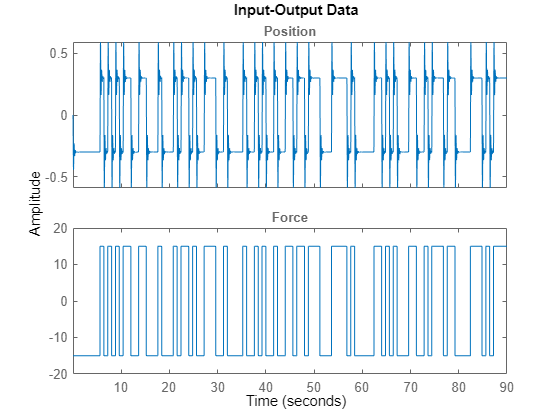

load("data1.mat");
%Some housekeeping 
data1.TimeUnit='seconds';
data1.InputName='Force';
data1.InputUnit='N';
data1.OutputName='Position';
data1.OutputUnit='m';

%Plot imput/output data for both experiments
figure(4)
plot(data1)


%Split input/output data in identification and validation set 
 IddSet=data1(1:4500);
 ValidationSet=data1(4501:end);

### **6 Apply System identification**

Once the needed data is created and separated into diferent set. We can go further with the system identification part. The first model to evaluate is  an impulse  model since this model is non parametric and it gives a first imprecion about the behaviour of the system. For the impulse model the first 140 samples were used. This is enough to campure a comprete step responsen of the system to the first time steady state value (see figure 4)

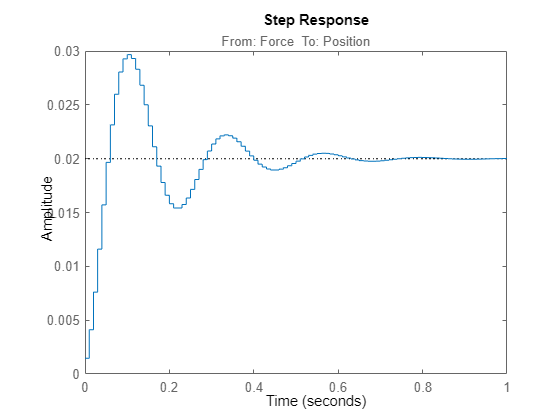

SystImpulse=impulseest(IddSet,140);
step(SystImpulse)

As can be seen in the figure above the step response of the FIR model behaves as a second order underdamped system. This gives an indication of sysem order for the parametric models. 

#### **a) ARX model**

From the output response can be clearly seen that the system behaves as an second underdaped system. It is clearly not a first order system.

To evaluate diferent posibilities (number of poles and zeros), the command struc, arx struc and selstruc are used.

na=2:5;      %number of poles from 2 to 5
nb=1:5;      %number of zeros from 1:5
nk=0:10;       %Delay from 0:5 sampples
NN=struc(na,nb,nk);  
order=selstruc(arxstruc(IddSet(:,:),ValidationSet(:,:),NN))

order =      2     1     0


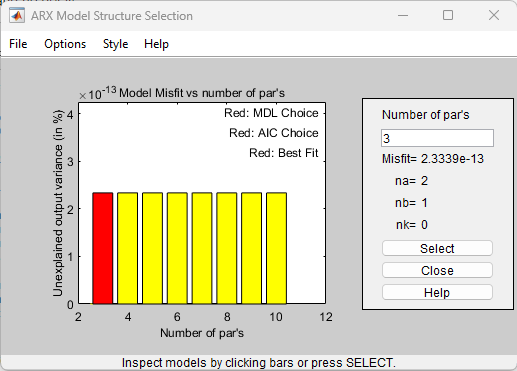

As can be seen in the figure above, both, the MDL and the AIC choice gives the best option to be a system with 2 poles 1 zero and no delay. Folleing this advice model is created with the given configuration.

SysARX = arx(IddSet,order)

SysARX =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.806 z^-1 + 0.8798 z^-2              
                                                   
  B(z) = 0.001466                                  
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=1   nk=0
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "IddSet".
Fit to estimation data: 100% (prediction focus)  
FPE: 3.886e-31, MSE: 3.878e-31                   


The ARX model has a prediction focus fit of 100% as given by the fit to estimation data. The model is further validated using the validation data. As seen below, the model also exhibits 100%fit for the validation model. This is extremely high and needs further inspection. 

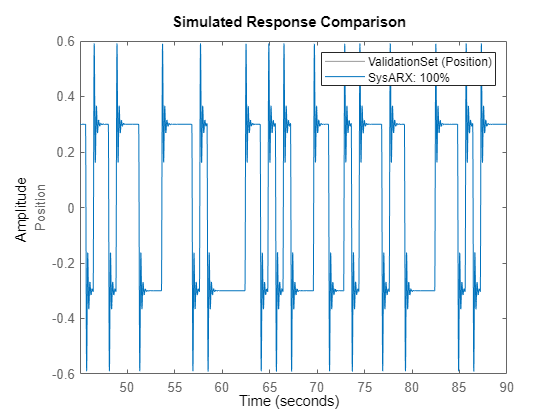

compare(ValidationSet,SysARX)

The residuals of the model are checked using the resid command. The model shows very high autocorrelation, which means that past samples can perfectly explain the point at lag=0. This may explain the extremely high fit of 100%. Due to the high autocorrelation, this model cannot be labeled as reliable. Also the crosscorrelation gives a large confident region, which tells us that the uncertainty in the crosscorrelation is high. 

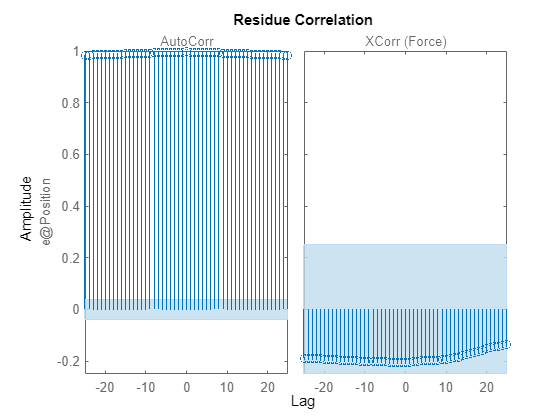

resid(ValidationSet,SysARX)

Given the fact that ARX model is a discrete model and there is no delay programmed in the system simulation, a sample delay of 1 has to be adde to the model. Therefore a second ARX is fitted to the data. This time a delay of 1 is added. 

NN=struc(2,1,1);  
order=[2,1,1]

order =      2     1     1


SysARX2=arx(IddSet,order)

SysARX2 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.808 z^-1 + 0.8814 z^-2              
                                                   
  B(z) = 0.001446 z^-1                             
                                                   
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=1   nk=1
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "IddSet".
Fit to estimation data: 98.8% (prediction focus) 
FPE: 1.327e-05, MSE: 1.324e-05                   


The second ARX model has a "worse" fit then the first model. However the fit is still above 90% fit. 

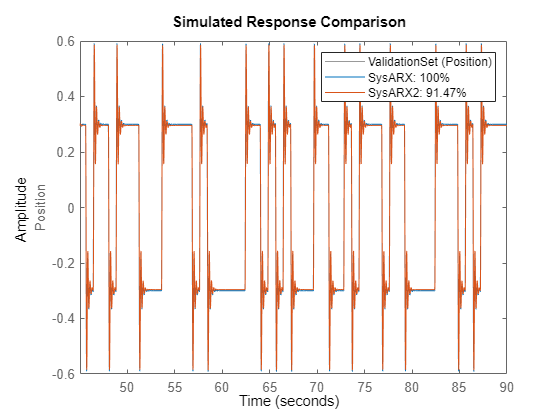

compare(ValidationSet,SysARX,SysARX2)

A considerable difference is the residuals. The sysARX2 exhibit no autocorrelation nor cross-correlation. This has to be the influence of the added delay of 1 sample.

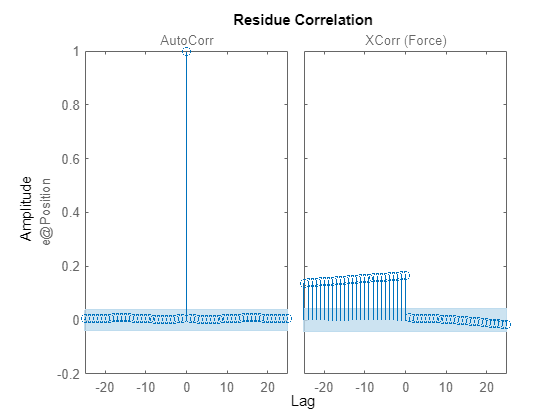

resid(ValidationSet,SysARX2)

**b)Tranfer functions**

The second model to fit to the data is a transfer function. First the delay is expected to be zero since there is no delay programed in the system model. 

This is confirmed using the delaysest command:

delayest(IddSet)

ans = 0

Next, a continuous transfer function is calculated. Given the behavior of the FIR model, a transfer function with two poles and one zero was chosen.

SysTF=tfest(IddSet,2,1)

SysTF =
 
  From input "Force" to output "Position":
    0.2496 s + 15.61
  ---------------------
  s^2 + 13.77 s + 783.8
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "IddSet".
Fit to estimation data: 98.2%                      
FPE: 3.019e-05, MSE: 3.011e-05                     


This gives an fit to estimation data of 98.2% and a fit to the validation data of 98.32 wich is good. 

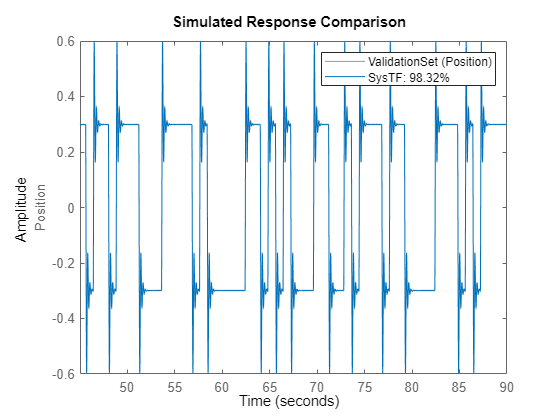

figure(5)
compare(ValidationSet,SysTF);

However the residuals of the model indicates high autocorrelation and also a bit of crosscorrelation.This indicates that we are missing some noise/distrubance dynamis and maybe also model dynamics. As Lennart Ljung explains in his the book System Identification theory for the user   :

*A clear peak a lag k shows that the effect from input u(t-k) on y(t) is not properly described. A rule of thumb is that a slowly varying cross-correlation function outside the confidence region is an indication of too few poles, while sharper peaks indicate too few zeros or wrong delays.*

Examining the crosscorrelation for a positive lag and following the rule of thumb given by  Ljung, one can say that the used transfer function is missing poles. Therefore a second transfer function is fitted to the data. 

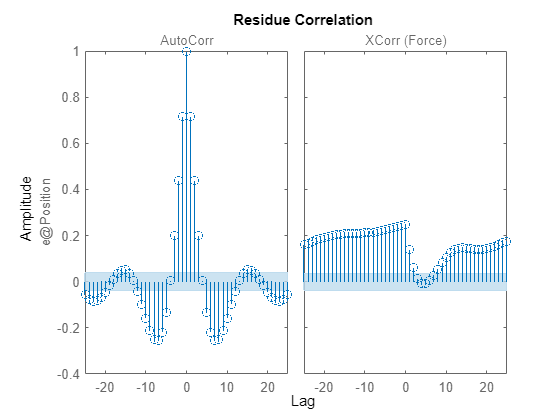

figure(7)
resid(IddSet,SysTF)

For the second transfer function, 3 poles and 2 zeros are used.

SysTF2=tfest(IddSet,3,2)

SysTF2 =
 
  From input "Force" to output "Position":
      0.6852 s^2 + 89.42 s + 5103
  -----------------------------------
  s^3 + 337.9 s^2 + 4950 s + 2.554e05
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "IddSet".
Fit to estimation data: 98.8%                      
FPE: 1.331e-05, MSE: 1.325e-05                     


Checking the residuals of SysTF2 gives good auto and crosscorrelation results.  

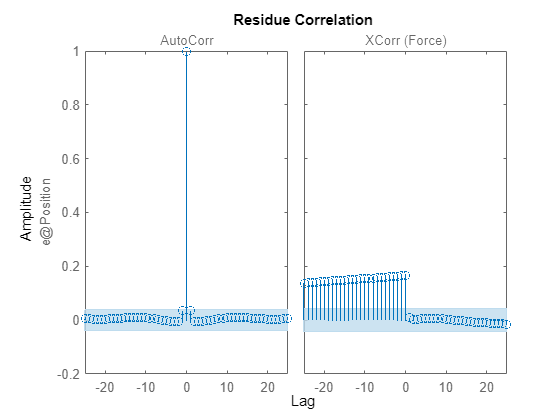

resid(ValidationSet,SysTF2)

Comparing both transfer functions on the validation data shows that SysTF2 has the best fit on the data with 98.89% fit. A high fit combined with no autocorrelation nor crosscorrelations (for lag>0) makes this model a good candidate. Note that there is crosscorrelation for a lag<0. This is a bit strange because then it says something about a correlation with the input in the future (which cannot be the case).

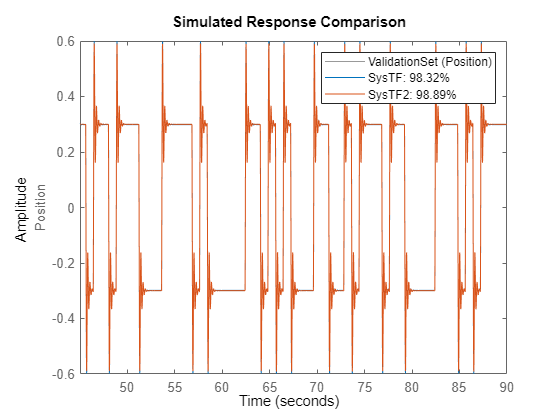

compare(ValidationSet,SysTF,SysTF2)

#### C) Proces model

As described by the FIR model at the beginning of the script, the system behaves as a second-order underdamped system. Therefore a process model of 2 poles underdamped with a zero  was chosen.

SysProc0=idproc("P2UZ");        %Process model wit 2 poles undedamped and une zero
SysProc=procest(IddSet,SysProc0)%Estimate the process model

SysProc =
Process model with transfer function:
                     1+Tz*s          
  G(s) = Kp * ---------------------- 
              1+2*Zeta*Tw*s+(Tw*s)^2 
                                     
         Kp = 0.019917               
         Tw = 0.035719               
       Zeta = 0.24592                
         Tz = 0.015992               
                                     
Parameterization:
    {'P2UZ'}
   Number of free coefficients: 4
   Use "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using PROCEST on time domain data "IddSet".
Fit to estimation data: 98.2%                        
FPE: 3.019e-05, MSE: 3.011e-05                       


The model shows good fit to the validation data 98.32%. However the residuals (line 88) shows high autocorrelation and crosscorrelation outside the confidence region. 

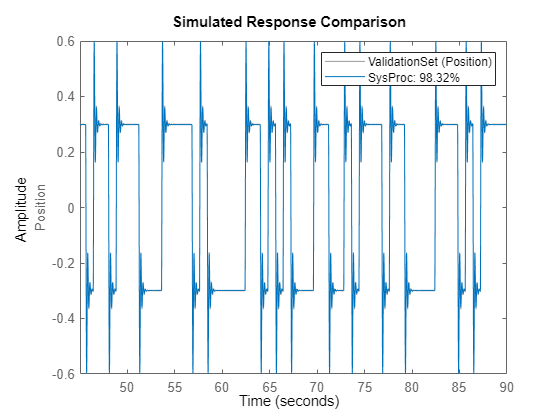

compare(ValidationSet,SysProc)

resid(IddSet,SysProc)

**Adding a disturbance model:**

A great option of the process models is the capability to include a disturbance model. Examining the system in Simulink, one may agree that a disturbance is being generated by the mass damper spring system connected to the Wheel and Axle B. This will generate a second order system disturbance. 

Therefore a second process model is estimated using a ARMA 2 disturbance model. 

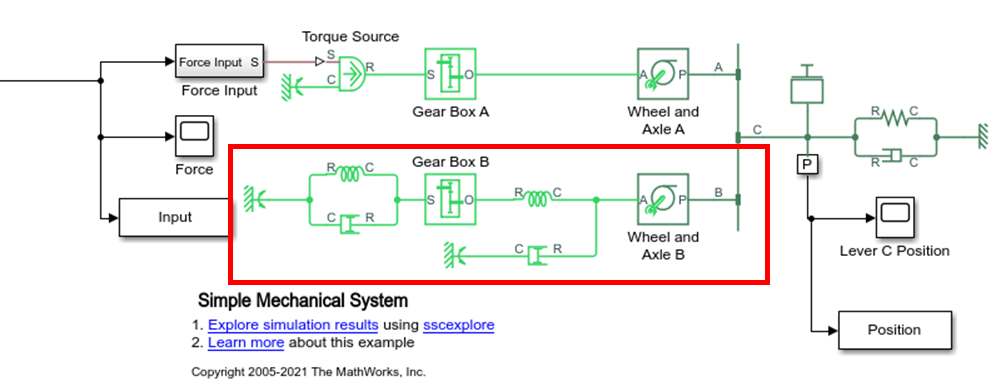

Opt=procestOptions;
Opt.DisturbanceModel='ARMA2'

Option set for the procest command:

      InitialCondition: 'auto'
      DisturbanceModel: 'ARMA2'
               Display: 'off'
           InputOffset: 'auto'
          OutputOffset: []
    EstimateCovariance: 1
        Regularization: [1×1 struct]
          SearchMethod: 'auto'
         SearchOptions: '<Optimization options set>'
                 Focus: 'prediction'
       WeightingFilter: []
          OutputWeight: []
              Advanced: [1×1 struct]

Description of options


SysProc2=procest(IddSet,SysProc0,Opt)

SysProc2 =
Process model with transfer function:                
                     1+Tz*s                          
  G(s) = Kp * ----------------------                 
              1+2*Zeta*Tw*s+(Tw*s)^2                 
                                                     
         Kp = 0.019716                               
         Tw = 0.037185                               
       Zeta = 0.21216                                
         Tz = 0.0058525                              
                                                     
An additive ARMA disturbance model has been estimated
      y = G u + (C/D)e                               
                                                     
      C(s) = s^2 + 148.3 s + 9945                    
      D(s) = s^2 + 6.502 s + 777.9                   
                                                     
Parameterization:
    {'P2UZ'}
   Number of free coefficients: 8
   Use "getpvec", "getcov" for parameters and their uncertai

A comparison of the fit of both process models shows a decrease in fit for the  SysProc2 with respect to SysProc. However, 88.99% is still an acceptable fit. 

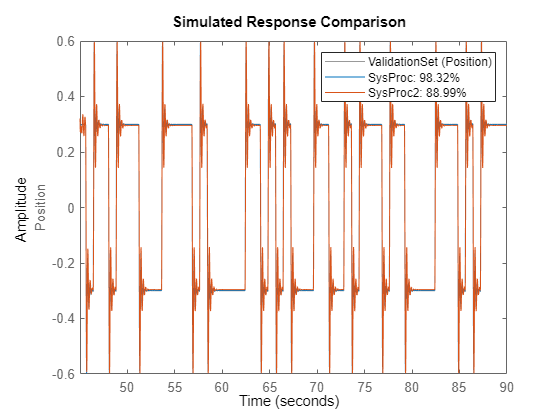

compare(ValidationSet,SysProc,SysProc2)

The residuals of the SysProc2 model show no autocorrelation nor crosscorrelation for lag>0. Based on this analysis, this model is superior to the first process model (SysProc).

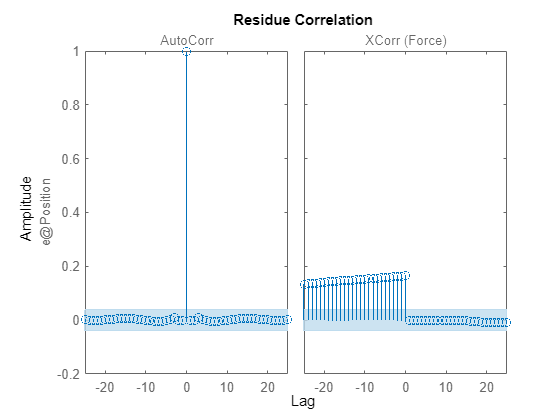

resid(IddSet,SysProc2)

**D)State space models**

The state space model is fitted using the n4sid command. A range of states is given from 1 to 5. The Hankel singular value shows that a state of 2 is the right amount of states. This is in line with the ARX models 

states=1:5;
Sysn4sid=n4sid(IddSet,states)

Sysn4sid =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
            x1       x2
   x1   0.8885   0.3412
   x2  -0.1881    0.918
 
  B = 
          Force
   x1  0.000989
   x2  0.000291
 
  C = 
                 x1      x2
   Position   4.111  -4.698
 
  D = 
             Force
   Position      0
 
  K = 
       Position
   x1    0.1337
   x2  -0.08869
 
Sample time: 0.01 seconds
  
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 10
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using N4SID on time domain data "IddSet".
Fit to estimation data: 98.8% (prediction focus)   
FPE: 1.328e-05, MSE: 1.323e-05                     


Note the high fit to estimation data of 98.8% wich at first look it seems to be very good. However this is bassed on prediction focus.This means projecting the model response steps ahead into the future using the current and past values of measured input and output values. The figure below shows that the simulation focus is 97.49% on the validation set. This is a bit  lower then the 98.8% on prediction focus. But it still a good fit.  

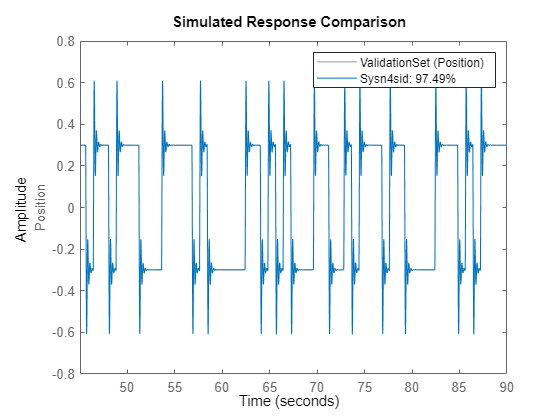

compare(ValidationSet,Sysn4sid)

The residual analysis shows good results i.e., no autocorrelation nor crosscorrelation with a lag of k>0.

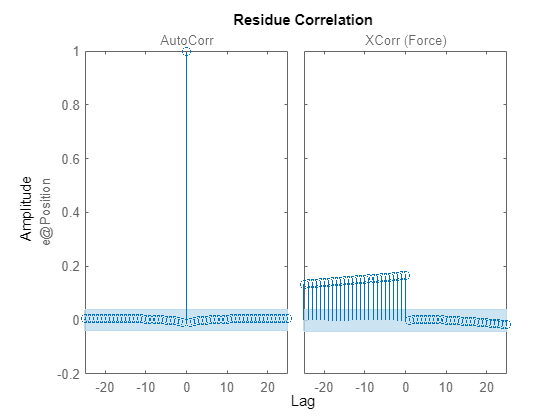

resid(IddSet,Sysn4sid)

### Model selection

The acceptance test is based on the fit and the residual analysis. From all the models fitted in this script,4 models are good candidates. The models  are:

- SysArx2: ARX model with 2 poles 1 zero and 1 delay

- SysTF2: Transferfunction with 3 poles and 2 zeros

- Sysn4sid: State space model with 2 states

-  Sysproc2: Processmodel with 2 poles underdamped with one zero and ARMA 2 disturbance

The step response is compared between the selected models and the FIR model. The FIR model is included because it is a non-parametric model. It is a good practice to compare the behavior of a non-parametric model with the four selected models (which, of course, are parametric) (Ljung, Lennard). As shown below, all four models have the same 2nd-order underdamped-like dynamics. In addition, it can be seen that all the models reach the same steady-state value. 

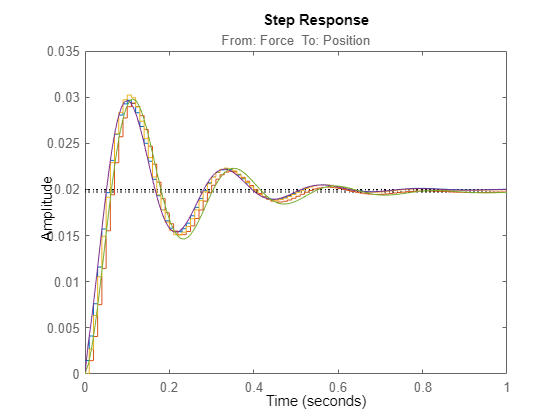

step(SystImpulse,SysARX2,Sysn4sid,SysTF2,SysProc2)

Next, the candidate models where compared in the figure bellow using the validation data. The transfer function model best fits the validation data, followed by the state space model. The process model SysProc2 has the lowes fit of all four models.

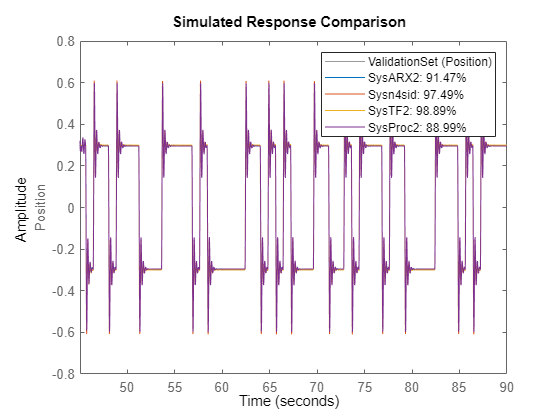

compare(ValidationSet,SysARX2,Sysn4sid,SysTF2,SysProc2)

A closed look shows clearly the differences between the models. The Process model exhibit a slight shift to the right and a small overshoot on the peaks compared to the validation data. The ARX fits the data better on the peaks but still has a slight shift. The State-space model shows only a little overshoot on the first peak, but it succeeds in predicting the rest of the data, i.e., no shift and no overshoot in the small peaks. The transfer function model fits the model very well. It has no shift nor overshoot in the peaks. 

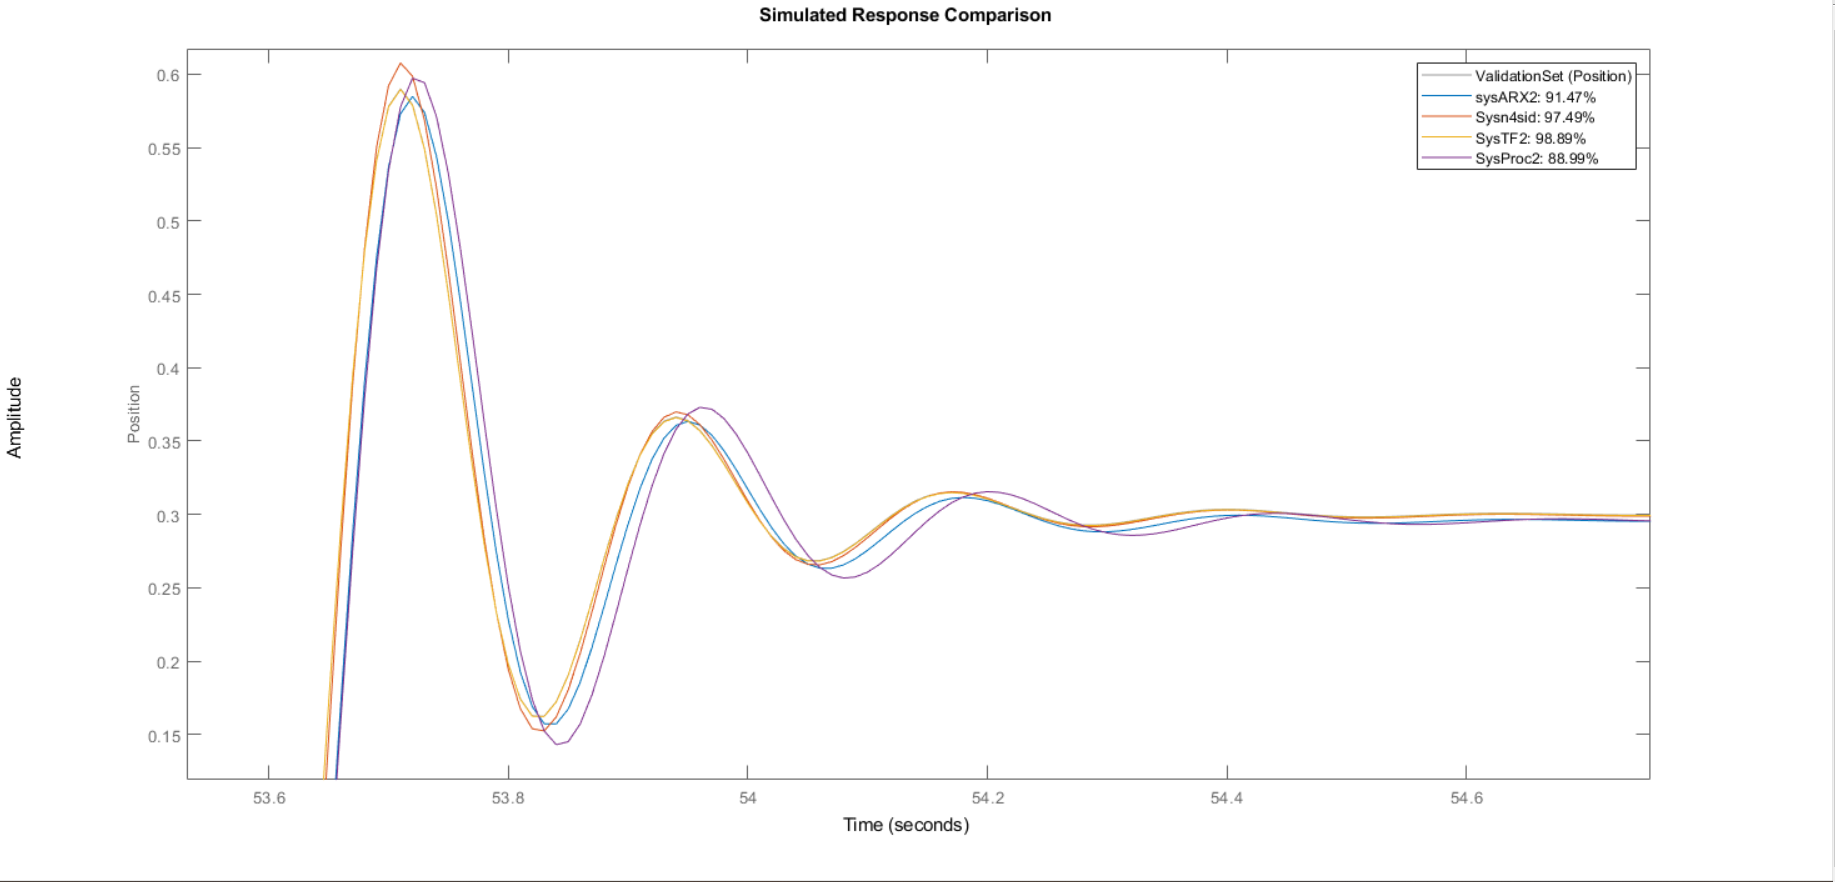

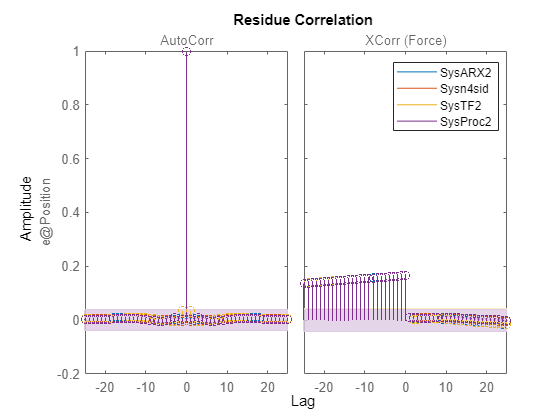

resid(ValidationSet,SysARX2,Sysn4sid,SysTF2,SysProc2)
legend

A comparison of the residuals in one figure was made in order to visualize the differences easily. As can be seen in the residue correlation figure, all model residuals are inside the confidence region for the crosscorrelation and autocorrelation.

Based on the residual analysis, all models meet the requirements. The process model Sysproc2 meets the residual tests, but a close look into the simulated response comparison shows overshooting and a shift in the prediction. The SysTF2(3 poles, 2 zeros transfer function) has the best fit but is at the same time only marginally better than the simpler second-order state space model Sysn4sid. Therefore it seems reasonable to pick the simpler state space model as the final choice.

**End of the live script. **